for xx = 1:numel(HFA_all)
tic

p_real = HFA_all(xx).stats_to_baseline.p;
t_real = HFA_all(xx).stats_to_baseline.t;

p_shuff = HFA_all(xx).stats_to_baseline.p_perm;
t_shuff = HFA_all(xx).stats_to_baseline.t_perm;



h = p_real<=0.05; % logical matrix



[labeledA, numRegions] = bwlabel(h , 8);

for n_cluster = 1:numRegions
    
    t_real(labeledA==n_cluster)=sum(t_real(labeledA==n_cluster));
    
end

Nshuff=100;
pool_shuff_t_val_upper = zeros(1,Nshuff); pool_shuff_t_val_lower = zeros(1,Nshuff); acc_shuff_t_val = zeros(numel(t_real));

for nshuff = 1:100
   
    h = p_shuff(nshuff,:)<=0.05;  shuff_t_val= t_shuff(nshuff,:);%individual shuff
    [labeledA, numRegions] = bwlabel(h , 8);
    for n_cluster = 1:numRegions , shuff_t_val(labeledA==n_cluster)=sum(shuff_t_val(labeledA==n_cluster));end
   pool_shuff_t_val_upper(nshuff) = max(shuff_t_val);
   pool_shuff_t_val_lower(nshuff) = min(shuff_t_val);
    %acc_shuff_t_val = min([shuff_t_val ; acc_shuff_t_val]);
end

p_lower = mean(t_real>pool_shuff_t_val_lower',1);
p_higher = mean(t_real<pool_shuff_t_val_upper',1);
clearvars -EXCEPT p_lower p_higher HFA_all xx;


sig=[];
for i = 1:numel(p_lower)
    
    if any(p_lower(i)<0.05)
        sig(i)=1;
     elseif any(p_higher(i)<0.05)
        sig(i)=-1;
    else
        sig(i)=0;
    
end
end

HFA_all(xx).stats_to_baseline.sig = sig; clear sig;
toc
end

count=1; sig_bins = [];
for i = 1:numel(HFA_all)
if any(HFA_all(i).stats_to_baseline.sig~=0)
        sig_bins(count,:) = HFA_all(i).stats_to_baseline.sig; count=count+1;
end
end

figure;imagesc(sig_bins)

for i = 1:size(sig_bins,1)
    start_bin(i,1) = find(sig_bins(i,:)~=0,1,'first');

end

a = horzcat(start_bin,[1:numel(start_bin)]');
a_sort = sortrows(a,1);

sig_bins_sorted = sig_bins(a_sort(:,2),:);

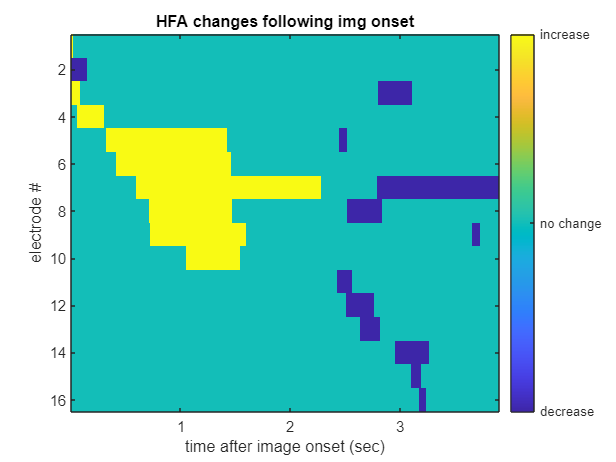


figure;imagesc(sig_bins_sorted);c = colorbar;
c.Ticks=[-1 0 1];c.TickLabels = {'decrease', 'no change', 'increase'};ylabel('electrode #');xlabel('time after image onset (sec)')
bin_centers = HFA_all(1).bin_centers_relative_to_img_ons;
zero_ind = find(bin_centers==0); bin_centers(1:zero_ind)=[];
xticks([find(bin_centers == 1000) find(bin_centers == 2000) find(bin_centers == 3000) find(bin_centers == 4000)])
xticklabels({'1','2','3','4'});title('HFA changes following img onset')

T = readtable('TWH175_Macro-Micro_ALL_atlases.xlsx');